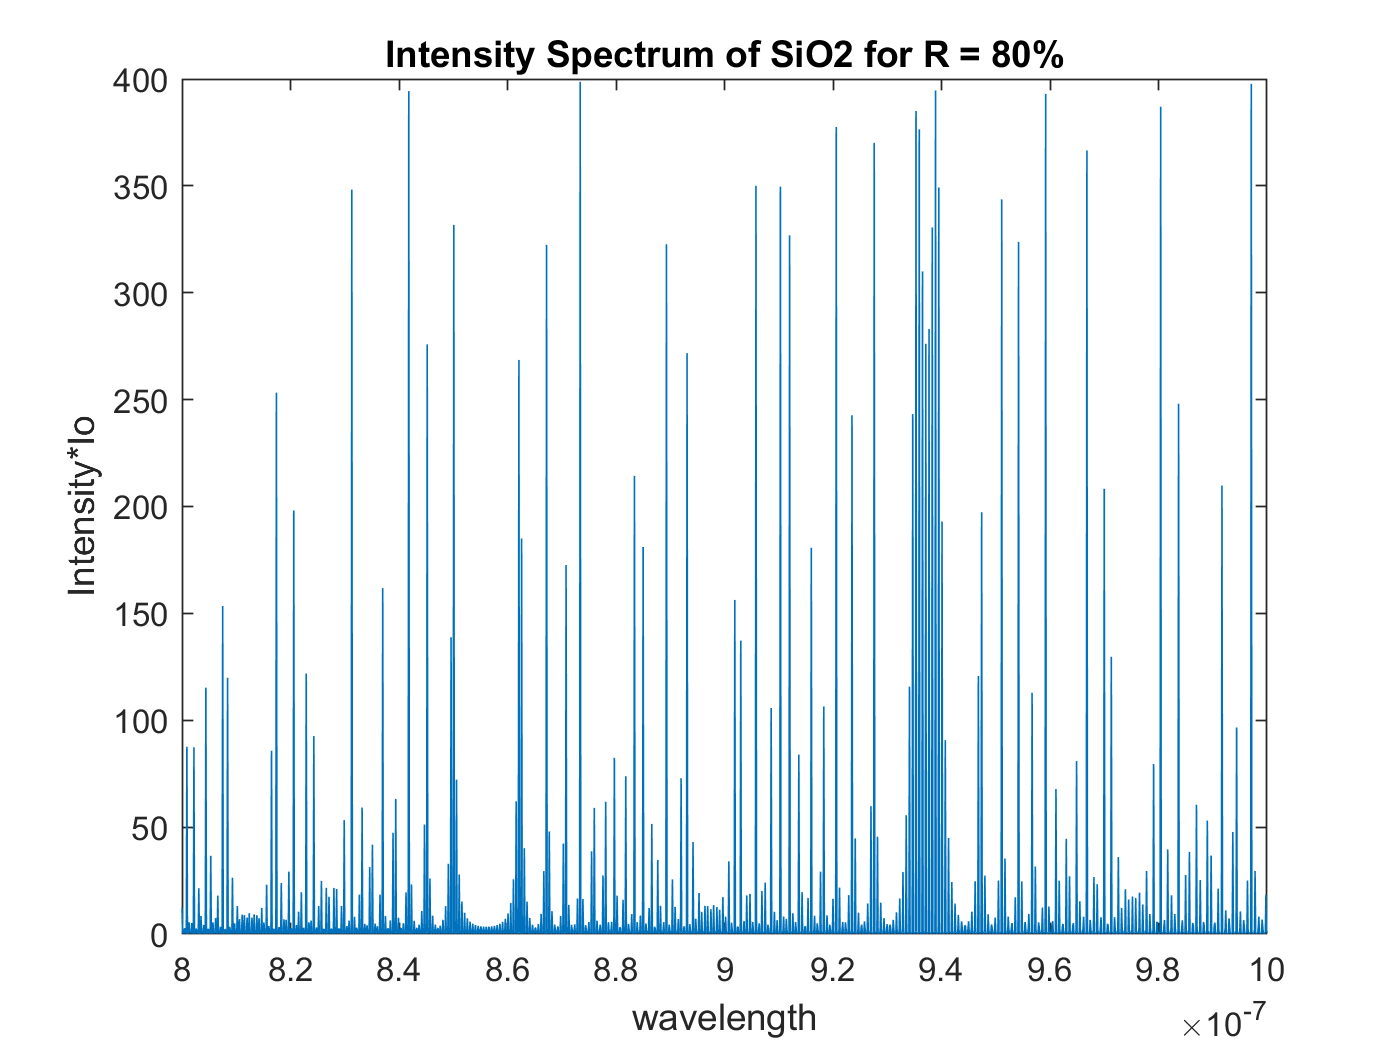

clc
clear

R = .95;
L = .5*10^(-3);
ts = .000001*10^(-6);
lambda = 1.5*10^-6ts:1.53*10^-6;
A1 = .696749;
A2 = .408218;
A3 = .890815;

C1S = .0690660*10^(-6);
C2S = .115662*10^(-6);
C3S = 9.900559*10^(-6);

n_SiO2 = sqrt(1+((A1*(lambda.^2))./(lambda.^2-C1S^2)+((A2*(lambda.^2))./(lambda.^2-C2S^2)))+((A3*(lambda.^2))./(lambda.^2-C3S^2)));
mpi = (2*n_SiO2.*L*pi)./lambda;

I = 1./((1-R)^2 + 4*R*sin(mpi).^2);
plot(lambda,I)
xlabel('wavelength');
ylabel('Intensity*Io');
title('Intensity Spectrum of SiO2 for R = 80%');


ns = 1510*10^(-9);
n_1510s= sqrt(1+((A1*(ns^2))./(ns^2-C1S^2)+((A2*(ns^2))./(ns^2-C2S^2)))+((A3*(ns^2))./(ns^2-C3S^2)));